data = importdata("Assignment_Data_SC42145_2022.mat")

data = struct with fields:
           A: [5×5 double]
           B: [5×3 double]
           C: [2×5 double]
           D: [2×3 double]
         FWT: [2×3 ss]
    WindData: [60001×2 double]


sys1 =
 
  A = 
              x1         x2         x3         x4         x5
   x1     -0.422    -0.2204          0    -0.2204          0
   x2    0.02328   -0.01085      -0.04  -0.009574          0
   x3          0          1          0          0          0
   x4     0.1455   -0.05984          0    -0.1651     -10.82
   x5          0          0          0          1          0
 
  B = 
              u1         u2         u3
   x1   -0.07988  -0.009564     0.2204
   x2  -0.006722          0   0.009574
   x3          0          0          0
   x4   -0.04202          0    0.05984
   x5          0          0          0
 
  C = 
       x1  x2  x3  x4  x5
   y1   1   0   0   0   0
   y2   0   0   1   0   1
 
  D = 
       u1  u2  u3
   y1   0   0   0
   y2   0   0   0
 
Continuous-time state-space model.




FWT = data.FWT;
A=data.A;
B=data.B;
C=data.C;
D=data.D;
%print(data)
sys1 = ss(A,B,C,D);

step(-FWT(1,1));

bode(-FWT(1,1));

margin(-FWT(1,1)); 

pzplot(-FWT(1,1));

stepinfo(-FWT(1,1));


% PID controller
Plant = -FWT(1,1);
Kp = 400;
Ki = 50.2;
Kd = 400;
Tf = 0.06;
C = pid(Kp,Ki,Kd,Tf)

C =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 400, Ki = 50.2, Kd = 400, Tf = 0.06
 
Continuous-time PIDF controller in parallel form.



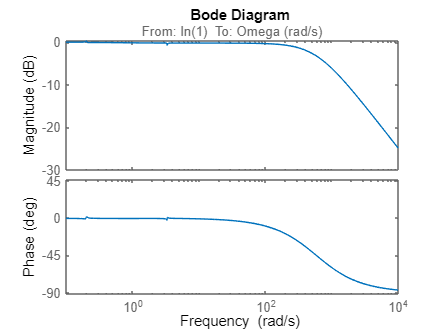



Polecancel = minreal(Plant*C); % To speed up the calculations
fbsys = feedback(Polecancel,1);
bode(fbsys);

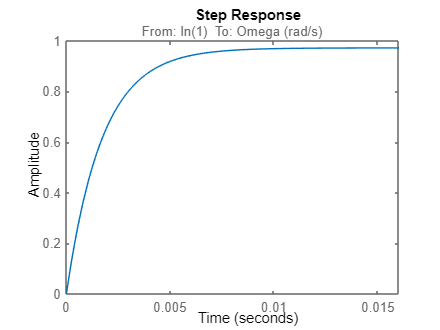

step(fbsys)

stepinfo(fbsys)

ans = struct with fields:
         RiseTime: 0.0043
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: 0.9016
      SettlingMax: 0.9725
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9725
         PeakTime: 0.0530


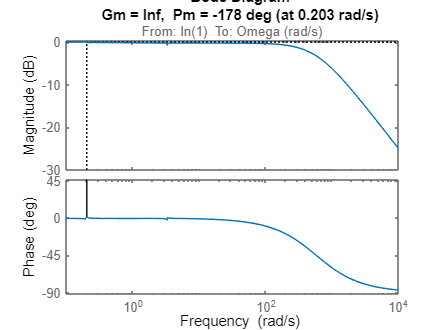

margin(fbsys);